1.生成语谱噪声，画出原信号的谱、噪声的谱。

导入原信号：[y, fs] = audioread(filename)

生成长周期频谱：sig = repmat(sig,1,10); [Pxx,w] = pwelch(sig,Windows,noverlap,nfft,fs); plot(w,Pxx); 其中还用到参数nfft=512; noverlap = nfft/2; Windows = hamming(nfft);

生成滤波器参数：b = fir2(3000,w/(fs/2),sqrt(Pxx/max(Pxx))); [h,wh] = freqz(b,1,128);

生成白噪声：N=length(x); noise = 1-2*rand(1,N); y= filter(b,1,noise);

clc,clear,close all;
%导入原信号
[x1,fs1]=audioread('C_01_01.wav');
[x2,fs2]=audioread('C_01_02.wav');
t1=linspace(0,length(x1)/fs1,length(x1));
t2=linspace(0,length(x2)/fs2,length(x2));
%播放确认导入无误
%sound(x1,fs1);
%sound(x2,fs2);
%画图
figure;
disp('原信号');

原信号


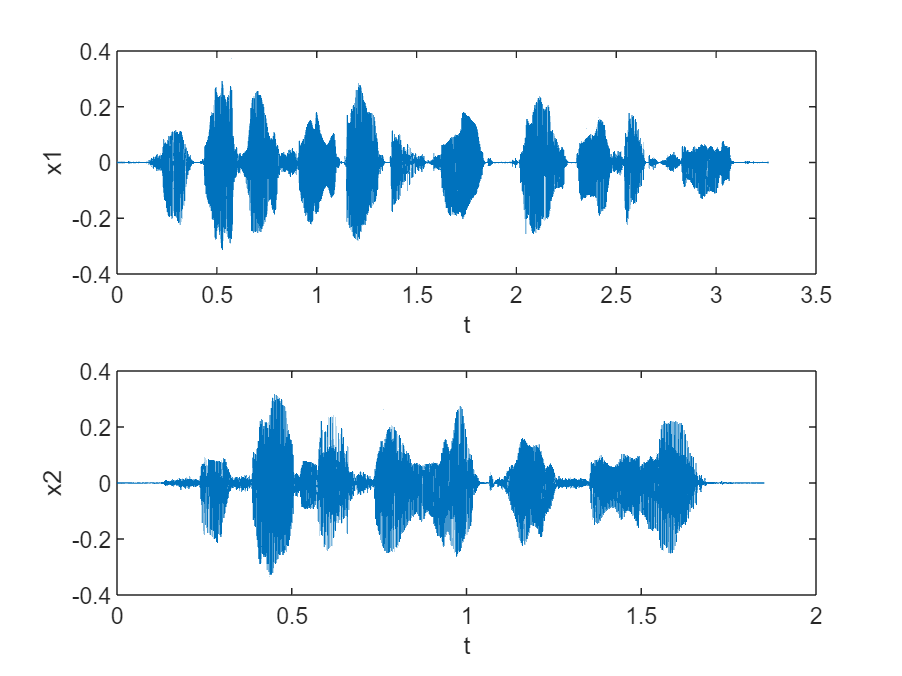

subplot(2,1,1),plot(t1,x1),xlabel('t'),ylabel('x1');
subplot(2,1,2),plot(t2,x2),xlabel('t'),ylabel('x2');

%设定参数
nfft=512;
noverlap=nfft/2;
Windows=hamming(nfft);
%产生更长的信号
x1long=repmat(x1,1,10);
x2long=repmat(x2,1,10);
%计算频谱密度
[Pxx1,w1]=pwelch(x1long,Windows,noverlap,nfft,fs1);
[Pxx2,w2]=pwelch(x2long,Windows,noverlap,nfft,fs2);
%生成滤波器参数
b1=fir2(3000,w1/(fs1/2),sqrt(Pxx1/max(Pxx1)));
b2=fir2(3000,w1/(fs2/2),sqrt(Pxx2/max(Pxx2)));
[h1,wh1]=freqz(b1,1,128);
[h2,wh2]=freqz(b2,1,128);
%生成白噪声
N1=length(x1);
noisebase1=1-2*rand(1,N1);
N2=length(x2);
noisebase2=1-2*rand(1,N2);
noise1=filter(b1,1,noisebase1);
noise2=filter(b2,1,noisebase2);
%画图
figure;
disp('语谱噪声-时域');

语谱噪声-时域


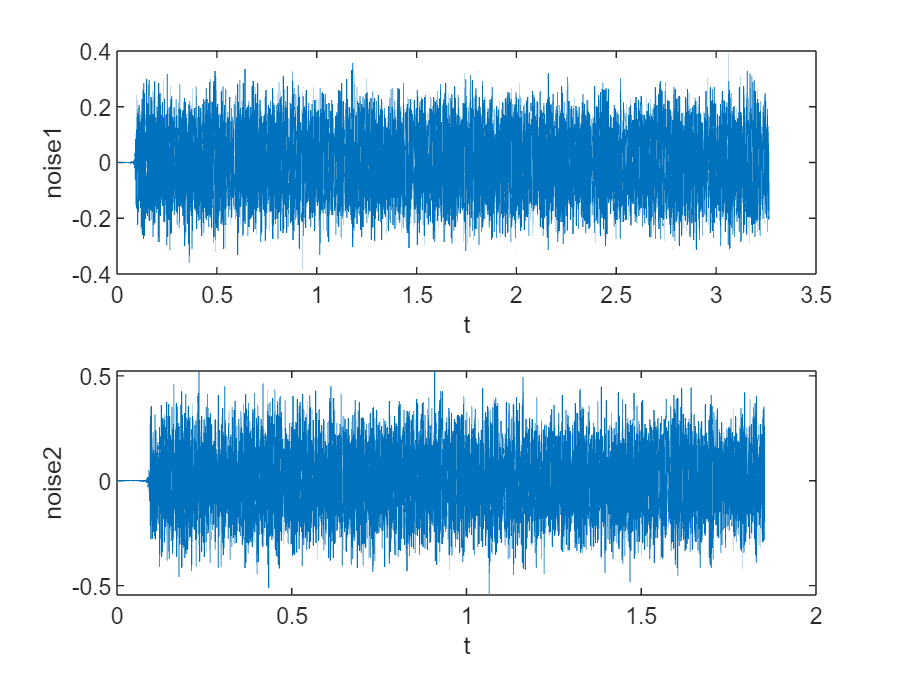

subplot(2,1,1),plot(t1,noise1),xlabel('t'),ylabel('noise1');
subplot(2,1,2),plot(t2,noise2),xlabel('t'),ylabel('noise2');

得到信号如图。

2.调整信噪比至-5dB，读语音信号x，标准化能量，为y，画出

信噪比公式：SNR=20*log10(norm(sig)/norm(noise))

-5dB <=> norm(sig)/norm(noise)=10^(-0.25)

调整能量：y’=y/norm(y)*norm(x)*2; % then y' has the twice energy of x

%得到噪声
soundnoise1=noise1/norm(noise1)*norm(x1)*(10^0.25);
soundnoise1=soundnoise1+x1.';
soundnoise2=noise2/norm(noise2)*norm(x2)*(10^0.25);
soundnoise2=soundnoise2+x2.';
%得到能量不变的带噪声信号
y1=soundnoise1/norm(soundnoise1)*norm(x1);
y2=soundnoise2/norm(soundnoise2)*norm(x2);
%画图
figure;
disp('带噪声的信号');

带噪声的信号


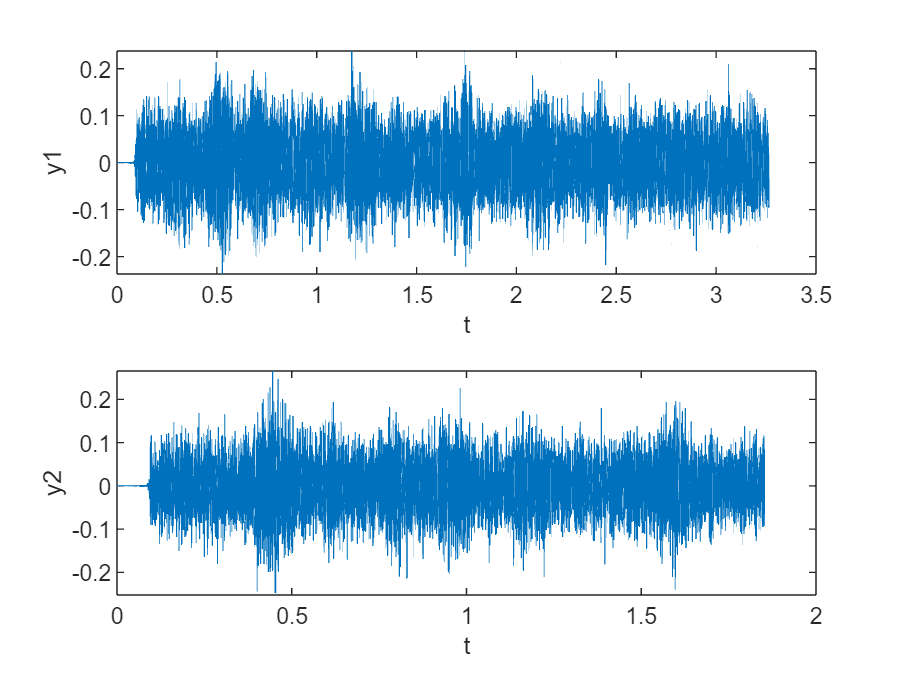

subplot(2,1,1),plot(t1,y1),xlabel('t'),ylabel('y1');
subplot(2,1,2),plot(t2,y2),xlabel('t'),ylabel('y2');

得到信号如图。